%% 0. Initialize Parameters 
n = 1250;                                                       % Number of locations to evaluate bridge failure 
L = 1250;                                                       % Length of bridge 
h = 75;                                                         %Height of cross-section
t = 1.27;                                                       %Thickness of the Matboard
x = linspace(0, L, n);                                          % Define x coordinate 
SFD_PL = zeros(1, n);                                           % Initialize SFD(x) 
TauU  = 4;
TauG = 2;
E = 4000;
miu = 0.2;                                                        
SigT = 30;                                                      % Tensile Strength
SigC = 6;                                                       % Compressive Strength
P = 1;                                                          % Input any arbitrary P value

%Call Functions
y_bar = 38.47092275028581

y_bar = 38.4709

I = 496208.4818148167

I = 4.9621e+05

Q = 8194.553206999999

Q = 8.1946e+03

Q_glue = (2*1.27*105)*(25.48)                                  % A_flange*d

Q_glue = 6.7955e+03

[SFD_PL, BMD_PL] = ApplyPL(550, P, x, SFD_PL, n)               % Construct SFD, BMD 

SFD_PL =          0    0.4811    0.4811    0.4811    0.4811    0.4811    0.4811    0.4811    0.4811    0.4811    0.4811    0.4811    0.4811    0.4811    0.4811    0.4811    0.4811    0.4811    0.4811    0.4811    0.4811    0.4811    0.4811    0.4811    0.4811    0.4811    0.4811    0.4811    0.4811    0.4811    0.4811    0.4811    0.4811    0.4811    0.4811    0.4811    0.4811    0.4811    0.4811    0.4811    0.4811    0.4811    0.4811    0.4811    0.4811    0.4811    0.4811    0.4811    0.4811    0.4811


BMD_PL =          0    0.4811    0.9623    1.4434    1.9245    2.4057    2.8868    3.3679    3.8491    4.3302    4.8113    5.2925    5.7736    6.2547    6.7358    7.2170    7.6981    8.1792    8.6604    9.1415    9.6226   10.1038   10.5849   11.0660   11.5472   12.0283   12.5094   12.9906   13.4717   13.9528   14.4340   14.9151   15.3962   15.8774   16.3585   16.8396   17.3208   17.8019   18.2830   18.7642   19.2453   19.7264   20.2075   20.6887   21.1698   21.6509   22.1321   22.6132   23.0943   23.5755


[SFD_PL, BMD_PL] = ApplyPL(L-1, P, x, SFD_PL, n)               % Construct SFD, BMD 

SFD_PL =          0    0.3028    0.3028    0.3028    0.3028    0.3028    0.3028    0.3028    0.3028    0.3028    0.3028    0.3028    0.3028    0.3028    0.3028    0.3028    0.3028    0.3028    0.3028    0.3028    0.3028    0.3028    0.3028    0.3028    0.3028    0.3028    0.3028    0.3028    0.3028    0.3028    0.3028    0.3028    0.3028    0.3028    0.3028    0.3028    0.3028    0.3028    0.3028    0.3028    0.3028    0.3028    0.3028    0.3028    0.3028    0.3028    0.3028    0.3028    0.3028    0.3028


BMD_PL =          0    0.3028    0.6057    0.9085    1.2113    1.5142    1.8170    2.1198    2.4226    2.7255    3.0283    3.3311    3.6340    3.9368    4.2396    4.5425    4.8453    5.1481    5.4509    5.7538    6.0566    6.3594    6.6623    6.9651    7.2679    7.5708    7.8736    8.1764    8.4792    8.7821    9.0849    9.3877    9.6906    9.9934   10.2962   10.5991   10.9019   11.2047   11.5075   11.8104   12.1132   12.4160   12.7189   13.0217   13.3245   13.6274   13.9302   14.2330   14.5358   14.8387


M_MatT_PL = zeros(1, n);
M_MatT_PL = MfailMatT(y_bar,I, SigT, BMD_PL, x, M_MatT_PL, 65)

M_MatT_PL = 	1.0e+05 *

         0    3.8695    3.8695    3.8695    3.8695    3.8695    3.8695    3.8695    3.8695    3.8695    3.8695    3.8695    3.8695    3.8695    3.8695    3.8695    3.8695    3.8695    3.8695    3.8695    3.8695    3.8695    3.8695    3.8695    3.8695    3.8695    3.8695    3.8695    3.8695    3.8695    3.8695    3.8695    3.8695    3.8695    3.8695    3.8695    3.8695    3.8695    3.8695    3.8695    3.8695    3.8695    3.8695    3.8695    3.8695    3.8695    3.8695    3.8695    3.8695    3.8695


M_MatC_PL = zeros(1, n);   
M_MatC_PL = MfailMatC(y_bar, I, SigC, BMD_PL, x, M_MatC_PL, 65)

M_MatC_PL = 	1.0e+05 *

         0    1.1223    1.1223    1.1223    1.1223    1.1223    1.1223    1.1223    1.1223    1.1223    1.1223    1.1223    1.1223    1.1223    1.1223    1.1223    1.1223    1.1223    1.1223    1.1223    1.1223    1.1223    1.1223    1.1223    1.1223    1.1223    1.1223    1.1223    1.1223    1.1223    1.1223    1.1223    1.1223    1.1223    1.1223    1.1223    1.1223    1.1223    1.1223    1.1223    1.1223    1.1223    1.1223    1.1223    1.1223    1.1223    1.1223    1.1223    1.1223    1.1223


V_fail = Vfail(2.54, I, Q, TauU)

V_fail = 615.2231

V_fail_glue = Vfail(22.54, I, Q_glue, TauG)

V_fail_glue = 3.2917e+03

V_Buck = VfailBuck(E, miu,62.46,215,t,I,2.54,Q)

V_Buck = 1.1815e+03


%BUCKLING MOMENT
[M_Buck_flange, P_Buck_flange] = MfailBuck("flange",y_bar,I,E,miu,62.46,BMD_PL, t, L)

M_Buck =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


M_Buck_flange = 	1.0e+04 *

         0    7.6983    7.6983    7.6983    7.6983    7.6983    7.6983    7.6983    7.6983    7.6983    7.6983    7.6983    7.6983    7.6983    7.6983    7.6983    7.6983    7.6983    7.6983    7.6983    7.6983    7.6983    7.6983    7.6983    7.6983    7.6983    7.6983    7.6983    7.6983    7.6983    7.6983    7.6983    7.6983    7.6983    7.6983    7.6983    7.6983    7.6983    7.6983    7.6983    7.6983    7.6983    7.6983    7.6983    7.6983    7.6983    7.6983    7.6983    7.6983    7.6983


P_Buck_flange =          0  405.1750  405.1750  405.1750  405.1750  405.1750  405.1750  405.1750  405.1750  405.1750  405.1750  405.1750  405.1750  405.1750  405.1750  405.1750  405.1750  405.1750  405.1750  405.1750  405.1750  405.1750  405.1750  405.1750  405.1750  405.1750  405.1750  405.1750  405.1750  405.1750  405.1750  405.1750  405.1750  405.1750  405.1750  405.1750  405.1750  405.1750  405.1750  405.1750  405.1750  405.1750  405.1750  405.1750  405.1750  405.1750  405.1750  405.1750  405.1750  405.1750


[M_Buck_tip, P_Buck_tip] = MfailBuck("tip",y_bar,I,E,miu,17.5,BMD_PL, t, L)

M_Buck =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


M_Buck_tip = 	1.0e+05 *

         0    1.0420    1.0420    1.0420    1.0420    1.0420    1.0420    1.0420    1.0420    1.0420    1.0420    1.0420    1.0420    1.0420    1.0420    1.0420    1.0420    1.0420    1.0420    1.0420    1.0420    1.0420    1.0420    1.0420    1.0420    1.0420    1.0420    1.0420    1.0420    1.0420    1.0420    1.0420    1.0420    1.0420    1.0420    1.0420    1.0420    1.0420    1.0420    1.0420    1.0420    1.0420    1.0420    1.0420    1.0420    1.0420    1.0420    1.0420    1.0420    1.0420


P_Buck_tip =          0  548.4025  548.4025  548.4025  548.4025  548.4025  548.4025  548.4025  548.4025  548.4025  548.4025  548.4025  548.4025  548.4025  548.4025  548.4025  548.4025  548.4025  548.4025  548.4025  548.4025  548.4025  548.4025  548.4025  548.4025  548.4025  548.4025  548.4025  548.4025  548.4025  548.4025  548.4025  548.4025  548.4025  548.4025  548.4025  548.4025  548.4025  548.4025  548.4025  548.4025  548.4025  548.4025  548.4025  548.4025  548.4025  548.4025  548.4025  548.4025  548.4025


[M_Buck_web, P_Buck_web] = MfailBuck("web",y_bar,I,E,miu,23.35,BMD_PL,t, L)

M_Buck =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


M_Buck_web = 	1.0e+05 *

         0    8.2626    8.2626    8.2626    8.2626    8.2626    8.2626    8.2626    8.2626    8.2626    8.2626    8.2626    8.2626    8.2626    8.2626    8.2626    8.2626    8.2626    8.2626    8.2626    8.2626    8.2626    8.2626    8.2626    8.2626    8.2626    8.2626    8.2626    8.2626    8.2626    8.2626    8.2626    8.2626    8.2626    8.2626    8.2626    8.2626    8.2626    8.2626    8.2626    8.2626    8.2626    8.2626    8.2626    8.2626    8.2626    8.2626    8.2626    8.2626    8.2626


P_Buck_web = 	1.0e+03 *

         0    4.3487    4.3487    4.3487    4.3487    4.3487    4.3487    4.3487    4.3487    4.3487    4.3487    4.3487    4.3487    4.3487    4.3487    4.3487    4.3487    4.3487    4.3487    4.3487    4.3487    4.3487    4.3487    4.3487    4.3487    4.3487    4.3487    4.3487    4.3487    4.3487    4.3487    4.3487    4.3487    4.3487    4.3487    4.3487    4.3487    4.3487    4.3487    4.3487    4.3487    4.3487    4.3487    4.3487    4.3487    4.3487    4.3487    4.3487    4.3487    4.3487



Pfail = FailLoad(SFD_PL, BMD_PL, V_fail, V_fail_glue, V_Buck, M_MatT_PL, M_MatC_PL, P_Buck_flange, P_Buck_tip, P_Buck_web)

Pfail = 1

max_SFD_PL = 1

max_BMD_PL = 189.3028

max_V_fail = 615.2231

max_V_Buck = 1.1815e+03

max_M_MatT_PL = 5.6113e+05

max_M_MatC_PL = 1.1223e+05

max_P_Buck_flange = 405.1750

max_P_Buck_tip = 548.4025

max_P_Buck_web = 4.3487e+03

V_fail_glue = 3.2917e+03

Pfail = 1

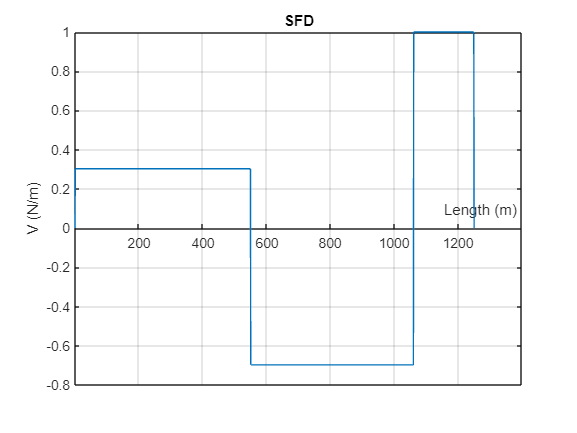

axis =   Axes with properties:

             XLim: [0 1400]
             YLim: [-200 200]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


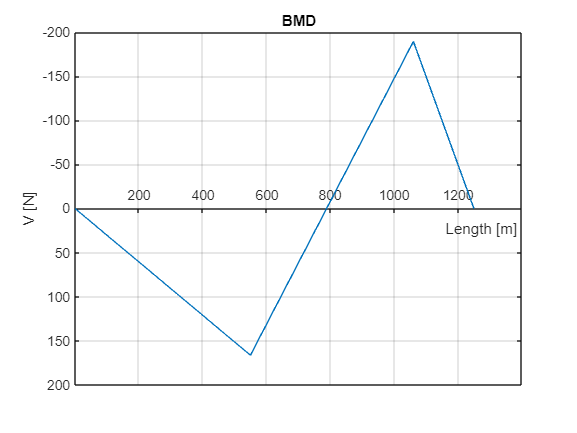

axis =   Axes with properties:

             XLim: [0 1]
             YLim: [0 1]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


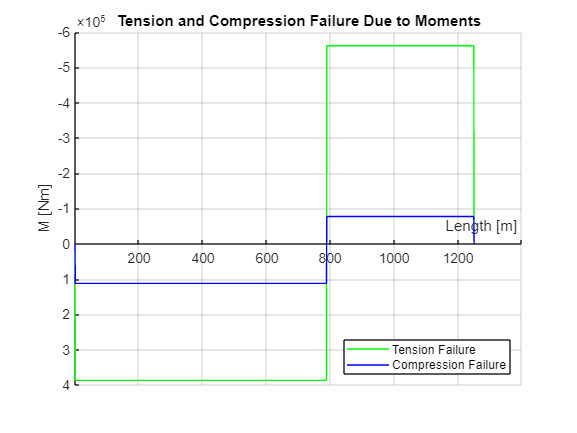

axis =   Axes with properties:

             XLim: [0 1]
             YLim: [0 1]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


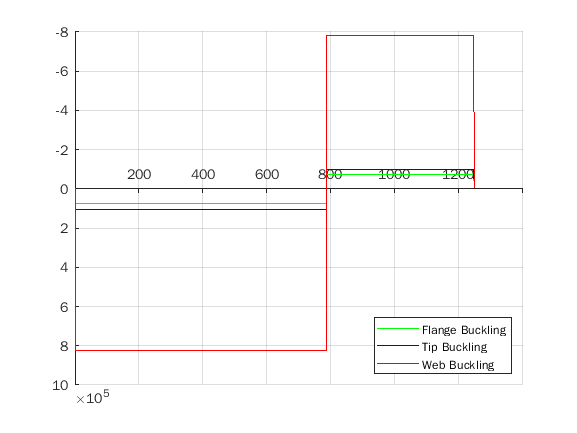


VisualizePL(x, SFD_PL, BMD_PL, M_MatT_PL, M_MatC_PL, M_Buck_flange, M_Buck_tip, M_Buck_web)

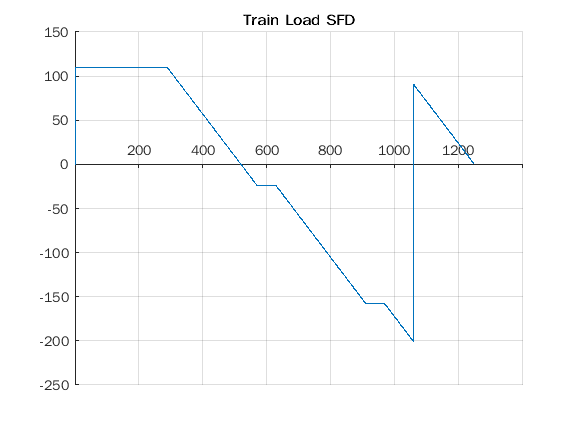

ax =   Axes with properties:

             XLim: [0 1]
             YLim: [0 1]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


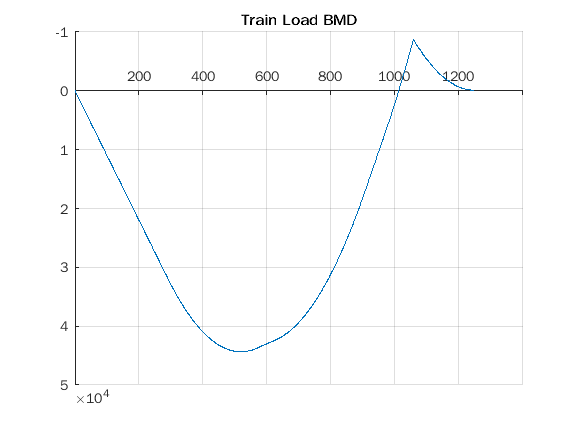

train(n,x)

function [] = VisualizePL(x, SFD_PL, BMD_PL, M_MatT_PL, M_MatC_PL, M_Buck_flange, M_Buck_tip, M_Buck_web)  
% Plots all outputs of design process 

%Plot SFD
figure;
plot(x, SFD_PL)
hold on;
grid on;
axis = gca;
axis.XAxisLocation = 'origin';
axis.YAxisLocation = 'origin';
title('SFD')
xlabel('Length (m)')
ylabel('V (N/m)')

%Plot BMD
figure;
plot(x, BMD_PL)
hold on;
grid on;
axis = gca;
axis.YDir = "reverse"
axis.XAxisLocation = 'origin';
axis.YAxisLocation = 'origin';
title('BMD')
xlabel('Length [m]')
ylabel('V [N]')

%Plot Tenion and Compression Failure due to Moments
figure;
hold on;
grid on;
axis = gca;                                           % To set properties of the axis
axis.YDir = "reverse"
axis.XAxisLocation = 'origin';
axis.YAxisLocation = 'origin';
plot(x, M_MatT_PL, '-g')
plot(x, M_MatC_PL, '-b')
title('Tension and Compression Failure Due to Moments')
legend('Tension Failure', 'Compression Failure')
legend('Location','southeast')
xlabel('Length [m]')
ylabel('M [Nm]')
 
figure;
hold on;
grid on;
axis = gca;
axis.YDir = "reverse"
axis.XAxisLocation = 'origin';
axis.YAxisLocation = 'origin';
plot(x, M_Buck_flange, '-g')
plot(x, M_Buck_tip, '-b')
plot(x, M_Buck_web, '-r')
legend('Flange Buckling', 'Tip Buckling', 'Web Buckling')
legend('Location','southeast')
end

function [ SFD, BMD ] = ApplyPL( xP, P, x, SFD, n ) 
% Constructs SFD and BMD from application of 1 Point Load. Assumes fixed location of supports 
% Input: location and magnitude of point load. The previous SFD can be entered as input to  
%  construct SFD of multiple point loads 
% Output: SFD, BMD both 1-D arrays of length n 
 
    %Locations of supports:
    supp_A = 2;                                                 %Support A
    supp_B = 1060;                                              %Support B

    A_y = P - (xP*P/supp_B);                                    %Reaction Force at support A
    B_y = (xP*P/supp_B);                                        %Reaction Force at support B
    BMD = zeros(1,n);
    
    
    
    if xP < supp_B
        for i = supp_A : xP                                     % Support A location to position of point load
            SFD(i) = SFD(i) + A_y;
        end

        for i = xP+1 : supp_B                                   % Position of point load + 1mm to Support B
            SFD(i) = SFD(i) + A_y - P;
        end
        
        for i = supp_B+1 : 1250                                 % Support B to the end of the bridge
            SFD(i) = SFD(i) + A_y - P + B_y;
        end
    end
    
    if xP > supp_B
   
        for i = (supp_A : supp_B)                              % Support A to Support B
            SFD(i) = SFD(i) + A_y;
        end
        
        for i = (supp_B+1 : xP)                                % Support B + 1mm to Position of point load
            SFD(i) = SFD(i) + A_y + B_y;
        end
    
        for i = (xP+1 : 1250)                                  % Point Load + 1mm to the end of the bridge
            SFD(i) = SFD(i) + A_y + B_y - P;
        end
    end
    
    for i = supp_A : 1250
        BMD(i) = BMD(i-1) + SFD(i);
    end
end

function [ V_fail ] = Vfail( b, I, Qcent, TauU ) 
% Calculates shear forces at every value of x that would cause a matboard shear failure 
% Input: Sectional Properties (list of 1-D arrays), TauU (scalar material property) 
% Output: V_fail a 1-D array of length n 
 
    V_fail = TauU .* I .* b ./ Qcent;
end 

function [ V_Buck ] = VfailBuck(E, miu,h,a,t,I,b,Q)
% Calculates shear forces at every value of x that would cause a shear buckling failure in the web 
% Input: Sectional Properties (list of 1-D arrays), E, mu (material property) 
% Output: V_Buck a 1-D array of length n 
    for i = 1:1250
        TauCr = (5*pi^2 * E)/(12*(1-miu^2))*((t/h)^2 + (t/a)^2);
        V_Buck = TauCr * I * b /Q;
    end

end

%Matboard Moment Faliure due to Tension
function [ M_MatT ] = MfailMatT(y_bar, I, SigT, BMD, x, M_MatT, h)%{Sectional Properties}, SigT, BMD )  
% Calculates bending moments at every value of x that would cause a matboard tension failure 
% Input: Sectional Properties (list of 1-D arrays), SigT (material property), BMD (1-D array) 
% Output: M_MatT a 1-D array of length n 
  
    for i = 2 : length(x)-1   
        if BMD(i) > 0 % If the moment is positive, the tension failure will be at the bottom 
            M_MatT(i) = (SigT * I) / (y_bar); 
        elseif BMD(i) < 0 % If the moment is negative, the tension failure will be at the top 
            M_MatT(i) = (-SigT * I) / (h - y_bar); 
        end 
    end 
end 

%Matboard Moment Faliure due to Compression
function [ M_MatC ] = MfailMatC(y_bar, I, SigC, BMD, x, M_MatC, h)%{Sectional Properties}, SigC, BMD ) % Similar to MfailMatT 
    for i = 2 : length(x)-1   
        if BMD(i) < 0 % Compression failure at bottom if M is -ve
            M_MatC(i) = -SigC * I / (y_bar); 
        elseif BMD(i) > 0 % Compression failure at top if M is -ve 
            M_MatC(i) = SigC * I / (h - y_bar); 
        end 
    end 
end

function [ M_Buck, PBuck ] = MfailBuck(part,y_bar,I,E,miu,b,BMD, t, L)
% Calculates bending moments at every value of x that would cause a buckling failure 
% Input: Sectional Properties (list of 1-D arrays), E, mu (material property), BMD (1-D array) 
% Output: M_MatBuck a 1-D array of length n 
    M_Buck = zeros(1,L)

    if part == "tip"
        SigCr = ((0.425*pi^2 * E)/(12*(1-miu^2)))*((t/b)^2);
    elseif part  == "flange"
        SigCr = ((4*(pi^2) * E)/(12*(1-miu^2)))*((t/b)^2);
    elseif part == "web"
        SigCr = ((6*pi^2 * E)/(12*(1-miu^2)))*((t/b)^2);
    end

    for i = 1:(L-1)
        if BMD(i) > 0                                   % Positive Moment
            M_Buck(i) = SigCr * I/(75 - y_bar);
            PBuck = M_Buck./166;
        end
        if BMD(i) < 0                                   % Negative Moment
            M_Buck(i) = -SigCr * I/y_bar;
            PBuck = M_Buck./190;
        end
    end
end

function [ Pfail ] = FailLoad(SFD_PL, BMD_PL, V_fail, V_fail_glue, V_Buck, M_MatT_PL, M_MatC_PL, P_Buck_flange, P_Buck_tip, P_Buck_web)
    max_SFD_PL = max(abs(SFD_PL));
    max_BMD_PL = max(abs(BMD_PL));
    max_V_fail = max(abs(V_fail));
    max_V_Buck = max(abs(V_Buck));
    max_M_MatT_PL = max(abs(M_MatT_PL));
    max_M_MatC_PL = max(abs(M_MatC_PL));                                        % Determine the maximum value in the array
    max_P_Buck_flange = max(abs(P_Buck_flange));
    max_P_Buck_tip = max(abs(P_Buck_tip));
    max_P_Buck_web = max(abs(P_Buck_web));
    minLoads = [max_SFD_PL, max_BMD_PL, max_V_fail, max_V_Buck, max_M_MatT_PL, max_M_MatC_PL, max_P_Buck_flange, max_P_Buck_tip, max_P_Buck_web, V_fail_glue];  %To find failure load, find the lowest P value that causes failure
    Pfail = min(minLoads)
    max_SFD_PL
    max_BMD_PL
    max_V_fail
    max_V_Buck
    max_M_MatT_PL
    max_M_MatC_PL
    max_P_Buck_flange
    max_P_Buck_tip
    max_P_Buck_web
    V_fail_glue

    %if minLoads > 0
     %   Pfail = min(minLoads)
    %else
     %   Pfail = 0
    %end
end 

function [] = train(n, x)

    SFD_long = NaN(1, 1250, 2210);
    BMD_long = NaN(1, 1250, 2210);
    for j = 1:2210

        SFD_PL = zeros(1, n);      % Initialize SFD(x)
        train_start = j;

        for j = (train_start:train_start + 280)
            start = j - 960;
            if (start>=1 & start<=1250)
                [SFD_PL, BMD_PL] = ApplyPL(start, 0.4761, x, SFD_PL, n);
            end
        end

        for j = (train_start + 340:train_start + 620)
            start = j - 960;
            if (start>=1 & start<=1250)
                [SFD_PL, BMD_PL] = ApplyPL(start, 0.4761, x, SFD_PL, n);
            end
        end

        for j = (train_start + 680:train_start + 960)
            start = j - 960;
            if (start>=1 & start<=1250)
                [SFD_PL, BMD_PL] = ApplyPL(start, 0.4761, x, SFD_PL, n);
            end
        end

        SFD_long(1, :, j) = SFD_PL(:);
        BMD_long(1, :, j) = BMD_PL(:);
    end

    figure;
    hold on;
    grid on;
    ax = gca;
    ax.XAxisLocation = 'origin';
    title('Train Load SFD')
    plot(x, SFD_long(1, :, 2210))

    figure;
    hold on;
    grid on;
    ax = gca;
    ax.YDir = "reverse"
    ax.XAxisLocation = 'origin';
    title('Train Load BMD')
    plot(x, BMD_long(1, :, 2210))
end
